**Exercise 3**

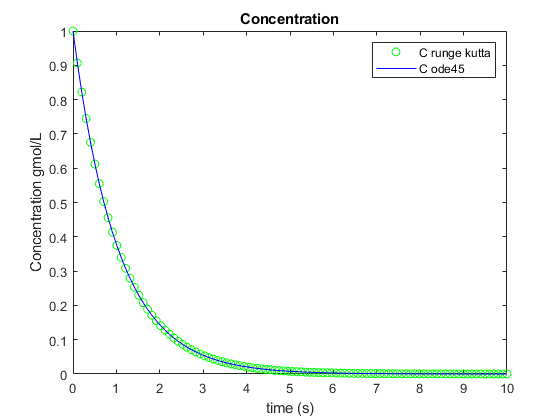

initialcond=[1; 15];% initial conditions
t=linspace(0,10);
func=@odesystem;
[result] = runge_kutta(func,t,initialcond);
C=result(1,:);
T=result(2,:);
[a,b]=ode45(func,t,initialcond);
C_ode45=b(:,1);
T_ode45=b(:,2);

plot(t,C,'go',t,C_ode45,'-b')
title('Concentration');
legend('C runge kutta','C ode45')
xlabel('time (s)');
ylabel('Concentration gmol/L');

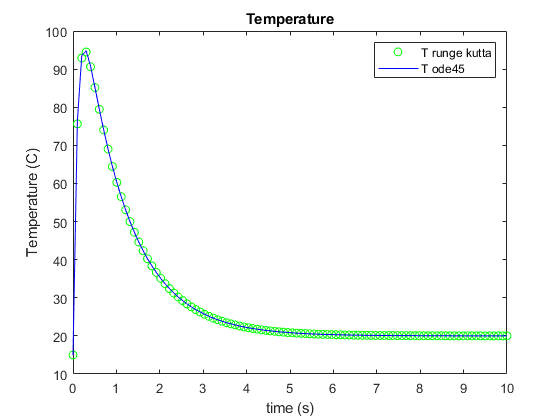


plot(t,T,'go',t,T_ode45,'-b')
title('Temperature');
legend('T runge kutta','T ode45')
xlabel('time (s)');
ylabel('Temperature (C)');

function [dpdt] = odesystem(t,p)
dpdt=zeros(2,1); 
C=p(1); T=p(2);
dpdt(1)= -exp(-10/(T+273))*C; % conc ode
dpdt(2)=1000*exp(-10/(T+273))*C-10*(T-20); % temp ode
end

function [y] = runge_kutta(df,x,y0)
m = length(y0);
n = length(x);
% y is a matrix of size 'mxn'
y=zeros(m,n);
y(:,1)=y0;
for i=1:n-1
    h = x(i+1)-x(i);
    xi=x(i);
    yi=y(:,i);
    k1 = feval(df,xi,yi);
    k2 = feval(df,xi+0.5*h,yi+0.5*k1*h);
    k3 = feval(df,xi+0.5*h,yi+0.5*k2*h);
    k4 = feval(df,xi+h,yi+k3*h);
    y(:,i+1) = y(:,i) + h*(k1+2*k2+2*k3+k4)/6;
end
end